# Using VIC to model the Tuolumne River Basin

A demo for new users of the VICMATLAB Toolbox

Written 3/6/2020 JRS

This is a tutorial to demonstrate how to use VICMATLAB to prepare inputs for and analyze results from the VIC model. The test basin is the Upper Tuolumne River Basin, near Yosemite National Park, California.

Before running this code, make sure that all files and paths are set properly according to your system. You will need VIC-4 and VIC-5, as well as the VICMATLAB toolbox.

Obtain a shapefile of the study area. You can download this from the USGS National Map Viewer website here: [https://viewer.nationalmap.gov/basic/](https://viewer.nationalmap.gov/basic/)

The first step is to extract the Tuolumne River Basin in R. Here is some sample code.

`huc8 <- readOGR(".../Shape/WBDHU8.shp")`

`upptuo <- huc8[huc8$Name == "Upper Tuolumne",]`

`writeOGR(tuolumne, "./data/upptuo.shp", driver = "ESRI Shapefile", layer = "bdy)`

Load the RoutR package, and use it to make an elevation map masked to the basin (also in R).

`merit_mask <- raster(".../MERIT/DEM/Merged_1_16/merit_mask_1_16.tif")`

`merit_dem <- raster(".../MERIT/DEM/Merged_1_16/merged_merit_dem_1_16.tif")`

`upptuo_dem <- clip_raster(merit_dem, upptuo) # or see alternative method in R script.`

`writeRaster(upptuo_dem, "./data/revised_basin/upptuo_dem.tif", NAflag = 0, datatype = "INT2S")`

Download Livneh et al. (2013) or Livneh et al. (2015) NetCDF meteorological forcing data. We will use Livneh et al. (2013) data for this tutorial. The data can be downloaded from [https://www.esrl.noaa.gov/psd/data/gridded/data.livneh.html.](https://www.esrl.noaa.gov/psd/data/gridded/data.livneh.html.)

Make a basin mask from the DEM.

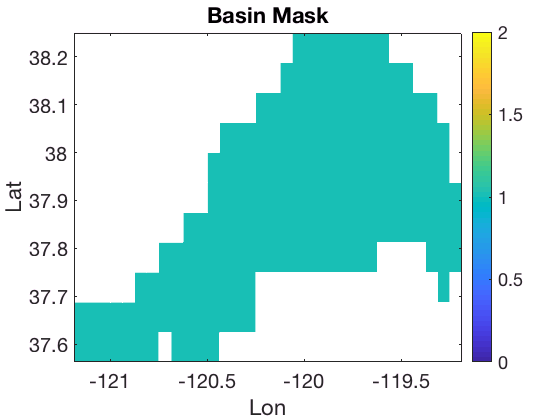

addpath(genpath('./vicmatlab1.0'));

[upptuo_dem, R, lon, lat] = geotiffread2('./data/revised_basin/upptuo_dem.tif');
basin_mask = double(upptuo_dem);
basin_mask(basin_mask == 0) = NaN;
basin_mask(~isnan(basin_mask)) = 1;

figure, plotraster(lon, lat, basin_mask,'Basin Mask','Lon','Lat', 1)


geotiffwrite('./data/revised_basin/upptuo_mask.tif', flipud(basin_mask), R);

Create the soil parameter file for the basin by subsetting the soil parameter file for the CONUS, from Livneh et al. (2013). This can be downloaded from the same website as the meteorological forcing data.

soilfile = '/Volumes/HD3/VICParametersCONUS/vic.soil.0625.new.cal.adj.conus.plus.crb.can_no_July_T_avg.txt';
disp('Loading soil parameter file')

Loading soil parameter file


soils = load(soilfile);
disp('Soil parameter file has been loaded')

Soil parameter file has been loaded



extent = '/Users/jschap/Documents/Codes/VICMATLAB/data/revised_basin/upptuo_mask.tif'; % extent of the study area; can be specified multiple ways
grid_decimal = 5; % number of decimals used in forcing filenames

outformat = 'livneh'; % format of input soil parameter file (number of soil layers)
outname = '/Users/jschap/Documents/Codes/VICMATLAB/data/revised_basin/upptuo_soils_livneh.txt';

generate_tif = 1;
setup = 'livneh';
[soils_tuo, soilvarpath] = subset_soils(soils, extent, outname, outformat, grid_decimal, generate_tif, setup);

Undefined function 'subset_soils' for input arguments of type 'double'.

Plot the soil parameters

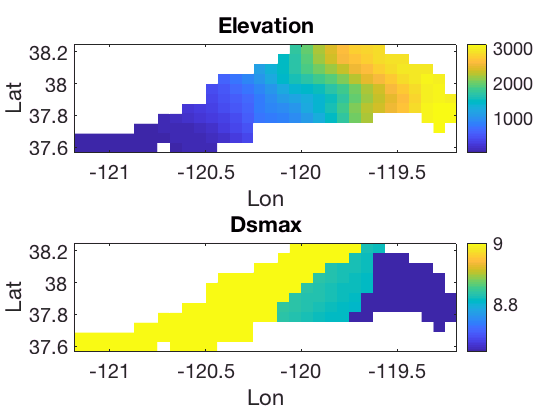

figure, subplot(2,1,1)
[elev, R, lon, lat] = geotiffread2(fullfile(soilvarpath, 'elev.tif'));
plotraster(lon, lat, elev, 'Elevation', 'Lon', 'Lat', 1)

subplot(2,1,2)
[dsmax, R, lon, lat] = geotiffread2(fullfile(soilvarpath, 'dsmax.tif'));
plotraster(lon, lat, dsmax, 'Dsmax', 'Lon', 'Lat', 1)

Create ASCII input files for the meteorological forcing data. Subset it to the basin.

force_in = '/Volumes/HD3/Livneh_2013/MetNC'; % directory where forcing data are located
numforcings = 4; % number of forcings in daily CONUS daily forcing file

% Beginning and ending years of simulation
beginyear = 2009;
endyear = 2011;

% Directory where clipped forcing files should be saved
force_out = ['./data/forc_' num2str(beginyear) '-' num2str(endyear)];

grid_decimal = 5; % number of decimals used in forcing filenames
maskname = './data/revised_basin/upptuo_mask.tif'; % basin mask

temp = subset_forcings(force_in, force_out, beginyear, endyear, grid_decimal, numforcings, maskname)

Error: File: subset_forcings.m Line: 8 Column: 52
Unbalanced or unexpected parenthesis or bracket.

Run the VIC model as a meteorological forcing disaggregator.

Create a global parameter file and run the following code to disaggregate the met. forcing data with MT-CLIM

disagg_force_out = ['./data/disagg_forc_' num2str(beginyear) '-' num2str(endyear)];
mkdir(disagg_force_out)
disp(['Created directory ' disagg_force_out ' for disaggregated forcings'])

Created directory ./data/disagg_forc_2009-2011 for disaggregated forcings


disp('Running met. forcing disaggregation')

Running met. forcing disaggregation


tic
system('/Volumes/HD3/SWOTDA/Software/VIC-VIC.4.2.d/src/vicNl -g ./data/global_param_disagg.txt')

***** VIC Version 4.2.d 2015-June-20 *****


 "./data/global_param_disagg.txt" has been
  opened for reading.... skipping header


 "./data/global_param_disagg.txt" has been
  opened for reading.... skipping header


 "./data/upptuo_soils_livneh.txt" has been
  opened for reading.


 "/Volumes/HD3/VICParametersCONUS/vic_veglib.txt" has been
  opened for reading.... skipping header


 "/Volumes/HD3/VICParametersCONUS/vic.veg.0625.new.cal.adj.can" has been
  opened for reading.

cell: 121188,  lat: 38.2188, long: -121.0938


 "./data/forc_2009-2011/data_38.21875_-121.09375" has been
  opened for reading.


 "./data/disagg_forc_2009-2011/full_data_38.21875_-121.09375" has been
  truncated or created for writing.
Initializing Forcing Data

Read meteorological forcing file

cell: 121933,  lat: 38.1562, long: -120.9062


 "./data/forc_2009-2011/data_38.15625_-120.90625" has been
  opened for reading.


 "./data/disagg_forc_2009-2011/full_data_38.15625_-120.90625" has been
  truncated or crea

ans =      0

toc

Run VIC for water years 2010-2011. This takes about 15 minutes on my computer.

Set up the global parameter file for this model run, first. This setup is for the Upper Tuolumne Basin, in energy balance mode, with the frozen soils module disabled to reduce computational requirements. Use the template global parameter file to generate the specific list of outputs that we are using in this example.

system('/Volumes/HD3/SWOTDA/Software/VIC-VIC.5.1.0.rc1/vic/drivers/classic/vic_classic.exe -g ./data/global_param.txt')

VIC Driver  : Classic
VIC Version : 5.0.1 February 1, 2017
VIC Git Tag : 
Compiled    : by jschap on american.seas.ucla.edu (APPLE) Nov 25 2019 08:50:27
Compiler    : clang
 version    : 10.0.0 (clang-1000.10.44.4)

  Variable Infiltration Capacity (VIC) macroscale hydrologic
  model version 5.0.1, Copyright (C) 2016 Computational
  Hydrology Group, Dept. of Civil and Environmental Engineering,
  University of Washington.  VIC comes with ABSOLUTELY NO
  WARRANTY. This is free software, you may redistribute it
  under certain conditions; see LICENSE.txt for details.

  Report Bugs and Issues to : https://github.com/UW-Hydro/VIC/issues
  VIC Users Email Listserve : vic_users@u.washington.edu 

[INFO] ../shared_all/src/vic_log.c:130: Initialized Log File: ./data/vic.log.20200310-69985.txt
[INFO] ./src/vic_classic.c:351: Completed running VIC Classic

------------------------------ VIC TIMING PROFILE ------------------------------

  Date                      : Tue Mar 10 12:41:08 2020
  C

ans =      0

Analyze the outputs from the VIC simulation. First, re-organize the VIC outputs using the following commands. 

`cd ./data/out_2009-2011/`

`mkdir eb; mv eb*.txt eb`

`mkdir wb; mv wb*.txt wb`

Then, process the VIC output data with VICMATLAB.

vic_out_dir = './data/out_2009-2011/'

vic_out_dir = './data/out_2009-2011/'

OUTPUT = check_outputs_wrapper(vic_out_dir);

soils = './data/upptuo_soils_livneh.txt'

maskname = './data/upptuo_mask.tif'

Read soil parameter file


Index exceeds matrix dimensions.

Error in convert_soil_parameters (line 101)
        A(landcells) = soils(landcells,k);

Plot the vegetation parameters

plot_vegetation_pars

Plot the forcing data

plot_force

Plot the flux outputs

plot_fluxes